%ПИД-регулятор kp = 10, ki = 5, kd = 8
% Constants
ke = 0.4987;
km = ke;
Tm = 0.0886;  
R =  8.8696;
L = 0.0047;
J = 0.0023;
target = 400;
U = 8.05;
M = 0.02; 

kp= 10; 
ki= 5; 
kd = 8;

data=readmatrix('Files_PID\PID_kp10_ki5_kd8.txt');
X=data(:,1);
Y=data(:,2);

Y_fixed=Y(length(Y))

Y_fixed = 400

e_fixed=Y(length(Y))-400 

e_fixed = 0

overshoot=(max(Y)-Y_fixed)/Y_fixed 

overshoot = 0.2100

for i=1:(length(Y))
    if (max(Y(i:length(Y)))<=Y_fixed*1.05) && (min(Y(i:length(Y)))>=Y_fixed*0.95)
        t_transition=X(i) 
       break
    end
end

t_transition = 5.4461

xlim([0 7])
ylim([0 500])
simout=sim('PID_model')

simout =   Simulink.SimulationOutput:

            simulinkPID: [1x1 timeseries] 
                   tout: [35930x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


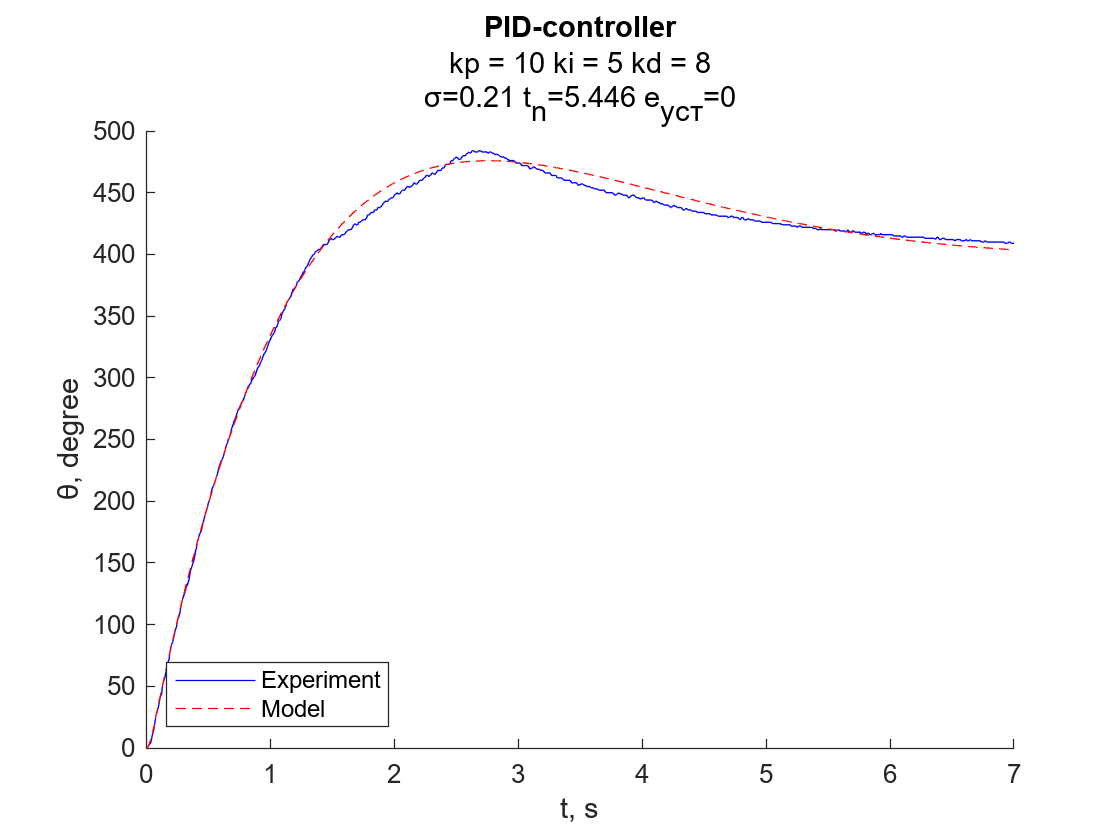


hold on
plot(X,Y,'b')
plot(simout.simulinkPID.Time, simout.simulinkPID.Data,'r--')
h2 = strcat('σ=',string(round(overshoot,3)), ' t_{n}=', string(round(t_transition,3)),' e_{уст}=', string(round(e_fixed,3)));
title('PID-controller',{'kp = 10 ki = 5 kd = 8',h2})
xlabel('t, s')
ylabel('θ, degree')
legend('Experiment', 'Model','Location','southwest')